clear
clc
close all

% Loading in functions and generating the dataset
load("Data_Problem1_regression.mat");
Ts = [T1 T2 T3 T4 T5];
nums = [7; 7; 5; 3; 2];
Tnew = sum(Ts*nums,2)/(sum(nums));
dataset = [X1 X2 Tnew];

% Generating random training, validation, and test sets
indices = [1:13600];
full_ind = datasample(indices,3000,2,"Replace",false);

train_ind = full_ind(:,1:1000);
test_ind = full_ind(:,1001:2000);
val_ind = full_ind(:,2001:3000);
train_set = dataset(train_ind, :);
val_set = dataset(val_ind, :);
test_set = dataset(test_ind, :);

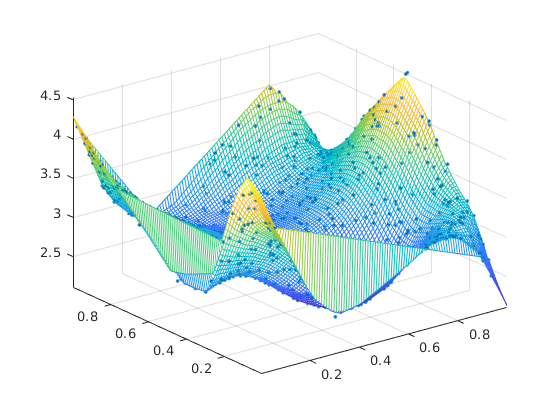

%plotting the training set
train_X1 = train_set(:,1);
train_X2 = train_set(:,2);
train_T = train_set(:,3);

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(train_X1,train_X2,train_T);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(train_X1,train_X2,train_T,'.');

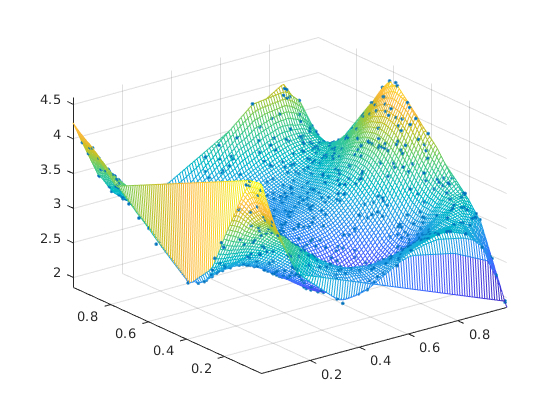

%Plotting the test set
test_X1 = test_set(:,1);
test_X2 = test_set(:,2);
test_T = test_set(:,3);

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(test_X1,test_X2,test_T);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(test_X1,test_X2,test_T,'.');

Build and train your feedforward Neural Network: use the training and validation sets. Build the ANN with 2 inputs and 1 output. Select a suitable model for the problem (number of hidden layers, number of neurons on each hidden layer). Select the learning algorithm and the transfer function that may work best for this problem. Motivate your decisions. When you try different networks, clearly say at the end which one you would select as the best for this problem and why.

% Building and training the network
layers = [30 30];
lm_net = fitnet(layers, 'trainbr');
lm_net.trainParam.epochs = 800;
lm_net.trainParam.max_fail = 10;
lm_net.numInputs = 2;
lm_net.inputConnect(1,1) = 1;
lm_net.inputConnect(1,2) = 1;
lm_net.inputs{1}.size = 1;
lm_net.inputs{2}.size = 1;
lm_net.divideFcn = 'divideind';
lm_net.divideParam.trainInd = train_ind;
lm_net.divideParam.valInd = val_ind;
lm_net.divideParam.testInd = test_ind;

% Formatting input data and configuring the network
X = {X1';X2'};
lm_net = configure(lm_net,X);

% Initialise and train the network
lm_net = init(lm_net);
[lm_net, lm_tr] = train(lm_net,X,Tnew');

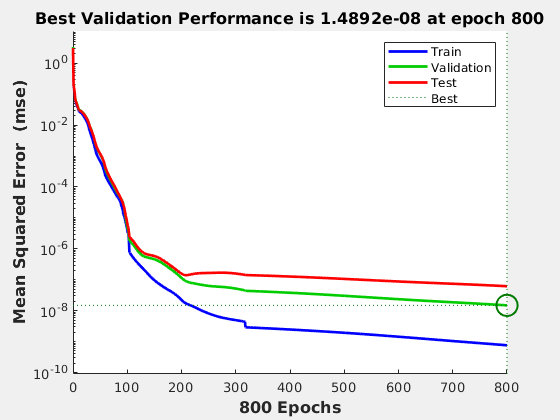

figure
plotperform(lm_tr);

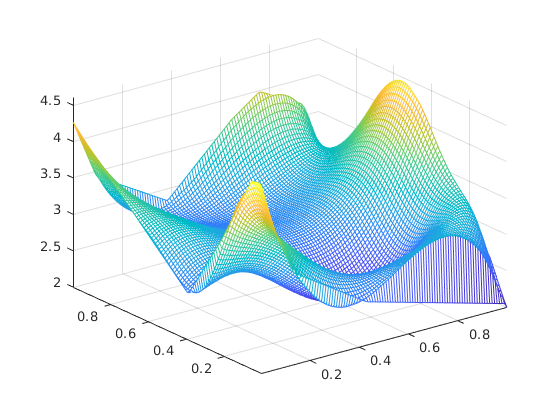

% Evaluating network on original inputs
t = cell2mat(lm_net(X))';

X1lin = linspace(min(X1), max(X1));
X2lin = linspace(min(X2), max(X2));

[X,Y] = meshgrid(X1lin,X2lin);

f = scatteredInterpolant(X1,X2,t);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight;

Tuning the network hyperparameters:

First will tune the architecture itself: number of neurons and number of layers

Then I will experiment with different activation functions.

Lastly I will look at the number of epochs.

% Determining the effective number of layers
neurons = 60;
test_errors = zeros(10,4);

for j=1:10
    for i=1:4
        layers = zeros(1,i);
        layers(1,:) = round(neurons/i);
        
        % Building and training the network
        net = fitnet(layers, 'trainlm');
        net.trainParam.epochs = 200;
        lm_net.trainParam.max_fail = 10;
        net.numInputs = 2;
        net.inputConnect(1,1) = 1;
        net.inputConnect(1,2) = 1;
        net.inputs{1}.size = 1;
        net.inputs{2}.size = 1;
        net.divideFcn = 'divideind';
        net.divideParam.trainInd = train_ind;
        net.divideParam.valInd = val_ind;
        net.divideParam.testInd = test_ind;
        
        X = {X1';X2'};
        net = configure(net,X);
        lm_net = init(lm_net);
        [net, tr] = train(net,X,Tnew');
        test_errors(j,i) = tr.best_tperf;
    end
end
layer_errors = mean(test_errors)

layer_errors = 	1.0e+-4 *

    0.1223    0.0468    0.0487    0.0730


neuron_errors =     0.0002    0.0008    0.0001    0.0002    0.0009    0.0004    0.0047    0.0002    0.0001    0.0062    0.0002    0.0002    0.0017    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002


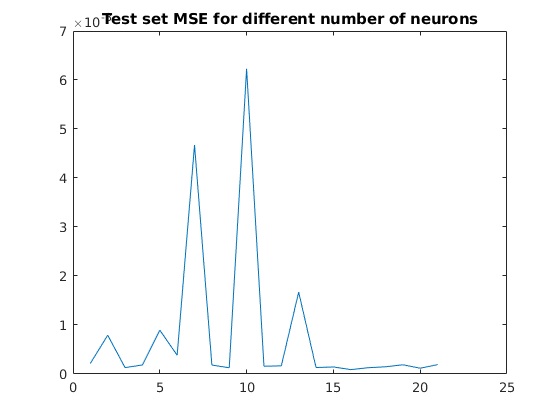

Unrecognized function or variable 'x'.

% Determining the effective number of neurons
layers = zeros(1,2);
test_errors = zeros(10,20);

for j=1:10
    for i=10:30
        layers(1,:) = i;
        
        % Building and training the network
        net = fitnet(layers, 'trainlm');
        net.trainParam.epochs = 50;
        net.trainParam.max_fail = 10;
        net.numInputs = 2;
        net.inputConnect(1,1) = 1;
        net.inputConnect(1,2) = 1;
        net.inputs{1}.size = 1;
        net.inputs{2}.size = 1;
        net.divideFcn = 'divideind';
        net.divideParam.trainInd = train_ind;
        net.divideParam.valInd = val_ind;
        net.divideParam.testInd = test_ind;
        
        X = {X1';X2'};
        net = configure(net,X);
        lm_net = init(lm_net);
        [net, tr] = train(net,X,Tnew');
        test_errors(j,i-9) = tr.best_tperf;
    end
end
neuron_errors = mean(test_errors)